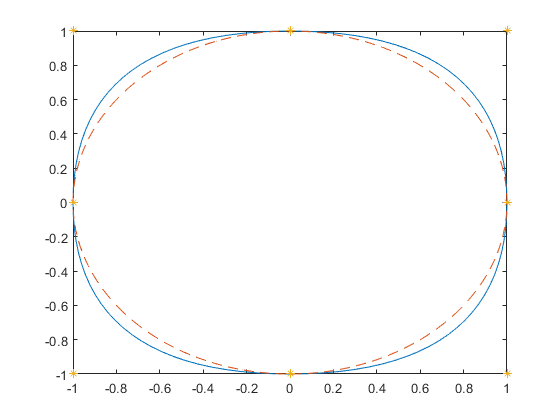

% knots for the construction of the approximation B-spline
K=[0,0,0, 0.25,0.25, 0.5,0.5, 0.75,0.75, 1,1,1];

% Points for the approximation
% the corners of the square and the centers of its sides
P=[[1;0],[1;1],[0;1],[-1;1],[-1;0],[-1;-1],[0;-1],[1;-1],[1;0]];

% approximation weights for approximation by B-spline curve
% all weights are 1
s2=1;
W=[1,s2,1,s2,1,s2,1,s2,1];

% % NURBS curve of degree 2, in fact, it is a B-spline because of weights
[ X,Y ] = nurbs(K,P,W,2);

% circle
tt=linspace(0,2*pi,201);
Cx=cos(tt);
Cy=sin(tt);

% comparing the B-spline curve and the circle
plot(X,Y,Cx,Cy,'--',P(1,:),P(2,:),'*')

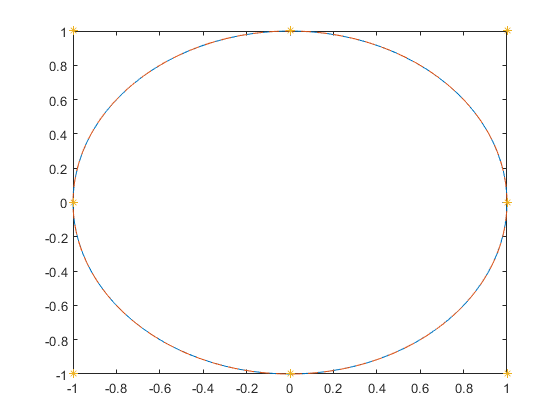

% approximation weights for the circle
s2=sqrt(2)/2;
W=[1,s2,1,s2,1,s2,1,s2,1];

% NURBS curve of degree 2
[ X,Y ] = nurbs(K,P,W,2);

% comparing the NURBS curve and the circle
plot(X,Y,Cx,Cy,'--',P(1,:),P(2,:),'*')

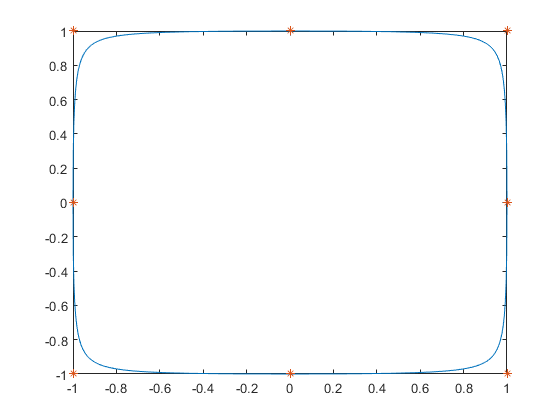

% approximation weights for approximation of the square
s2=5;
W=[1,s2,1,s2,1,s2,1,s2,1];

% NURBS curve
[ X,Y ] = nurbs(K,P,W,2);

plot(X,Y,P(1,:),P(2,:),'*')

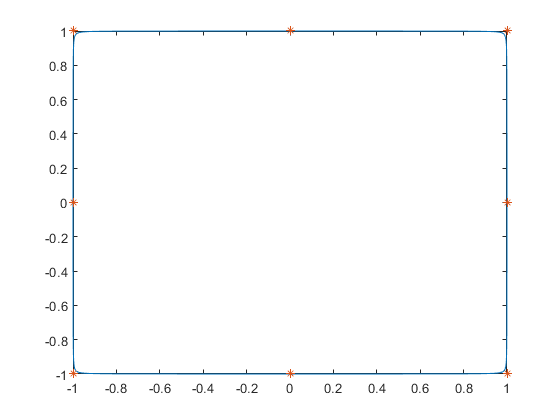


% approximation weights for approximation of the square
% high weights in the corners
s2=30;
W=[1,s2,1,s2,1,s2,1,s2,1];

% NURBS curve
[ X,Y ] = nurbs(K,P,W,2);

plot(X,Y,P(1,:),P(2,:),'*')

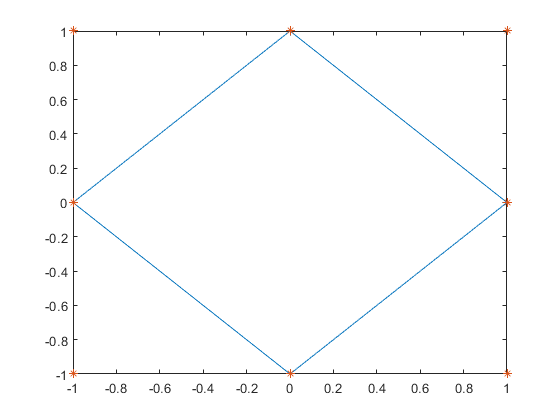


% approximation weights for approximation of the square
% zero weights in the corners
s2=0;
W=[1,s2,1,s2,1,s2,1,s2,1];

% NURBS curve
[ X,Y ] = nurbs(K,P,W,2);

plot(X,Y,P(1,:),P(2,:),'*')

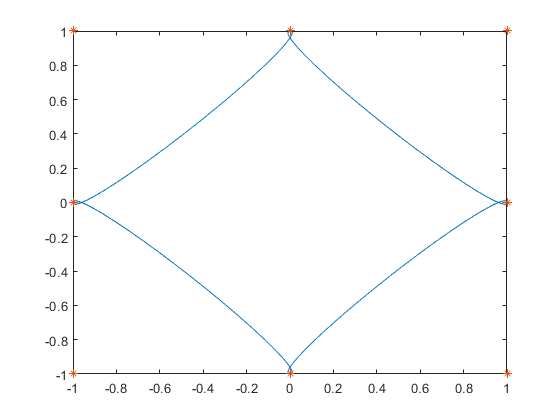


% approximation weights for approximation of the square
% negative weights in the corners

s2=-0.1;
W=[1,s2,1,s2,1,s2,1,s2,1];

% NURBS curve
[ X,Y ] = nurbs(K,P,W,2);

plot(X,Y,P(1,:),P(2,:),'*')

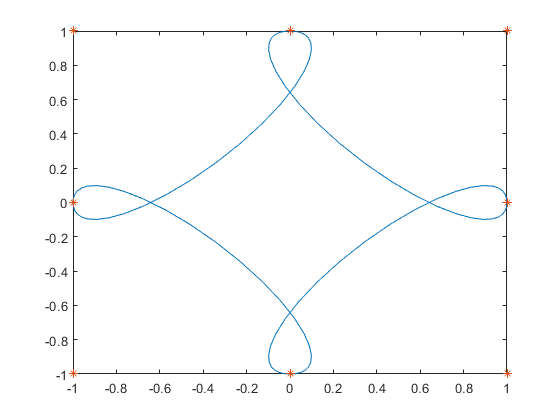


% approximation weights for approximation of the square
% negative weights in the corners
s2=-0.3;
W=[1,s2,1,s2,1,s2,1,s2,1];

% NURBS curve
[ X,Y ] = nurbs(K,P,W,2);

plot(X,Y,P(1,:),P(2,:),'*')

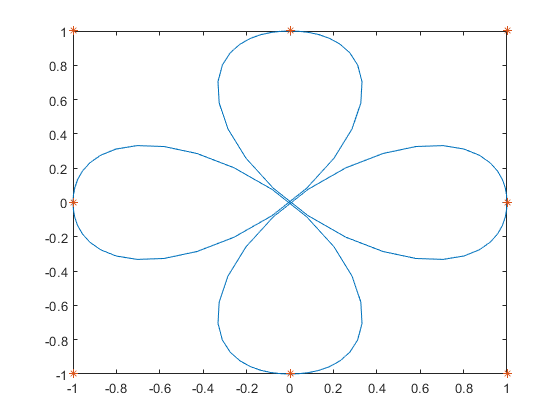


% approximation weights for approximation of the square
% negative weights in the corners
s2=-0.5;
W=[1,s2,1,s2,1,s2,1,s2,1];

% NURBS curve
[ X,Y ] = nurbs(K,P,W,2);

plot(X,Y,P(1,:),P(2,:),'*')